# NN处理

data = load('fisheriris')

data = 包含以下字段的 struct :
    species: {150×1 cell}
       meas: [150×4 double]


meas = data.meas;
species = data.species;

for i=1:max(size(meas,2))
t = meas(:,i);
t = (t-min(t(:)))./(max(t(:))-min(t(:)));
meas(:,i) = t;
end

## Classification – Single Layer Perceptron XOR

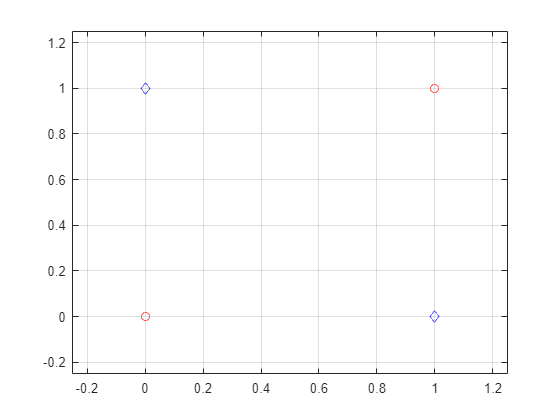

% Create the data.
X = [[0; 0] [0; 1] [1; 0] [1;1]];
T = [0 1 1 0];
% Plot the data.
figure(1)
plot(X(1, 1), X(2, 1), 'ro')
hold on
grid on
plot(X(1, 4), X(2, 4), 'ro')
plot(X(1, 2:3), X(2, 2:3), 'bd')
xlim([-.25, 1.25])
ylim([-.25, 1.25])


net = feedforwardnet(2, 'traingd');
% Configure the net
net.divideParam.trainRatio = 1; % training set [%]
net.divideParam.valRatio = 0; % validation set [%]
net.divideParam.testRatio = 0; % test set [%]
net.inputs{1}.processFcns = {}; % modify the process function for inputs
net.outputs{2}.processFcns = {}; % modify the process function for outputs
net.layers{1}.transferFcn = 'tansig'; % the transfer function for the first layer
net.layers{2}.transferFcn = 'tansig'; % the transfer function for the second layer
net.trainParam.lr = 1; % learning rate. You may need to adjust it in the experiment.


whos X T

  Name      Size            Bytes  Class     Attributes

  T         1x4                32  double              
  X         2x4                64  double              



net = train(net, X, T);
y = sim(net, [0; 0]) % return one output

y = 2.2293e-04

Y = sim(net, X) % return a vector of outputs

Y =     0.0002    0.9939    0.9876    0.0002


y = net([0; 0]) % return one output

y = 2.2293e-04

Y = net(X) % return a vector of outputs

Y =     0.0002    0.9939    0.9876    0.0002




% % change the transfer function for the first layer to Tanh
% net.layers{1}.transferFcn = 'logsig';
% % change the transfer function for the first layer to ReLU
% net.layers{1}.transferFcn = 'poslin';


## Classification – Iris dataset classification

data = load('fisheriris')

data = 包含以下字段的 struct :
    species: {150×1 cell}
       meas: [150×4 double]


meas = data.meas;
species = data.species;
for i=1:max(size(meas,2))
t = meas(:,i);
t = (t-min(t(:)))./(max(t(:))-min(t(:)));
meas(:,i) = t;
end

str = unique(species);
[found, idx] = ismember(species, str);
species_vec = full(ind2vec(idx'));

% Configure the net
net.inputs{1}.processFcns = {}; % modify the process function for inputs
net.outputs{2}.processFcns = {}; % modify the process function for outputs
net.layers{1}.transferFcn = 'logsig'; % the transfer function for the first layer
net.layers{2}.transferFcn = 'softmax'; % the transfer function for the second layer
net.performFcn = 'crossentropy'; %the loss function
net.trainParam.lr = 0.1; % learning rate. You may need to adjust it in the experiment

cvo = cvpartition(species, 'k', 2);
tridx = cvo.training(1);
teidx = cvo.test(1);
training_x = meas(tridx, :);
training_y = species_vec(:,tridx);
test_x = meas(teidx, :);
test_y = species(teidx);


whos training_x training_y

  Name             Size            Bytes  Class     Attributes

  training_x      75x4              2400  double              
  training_y       3x75             1800  double              



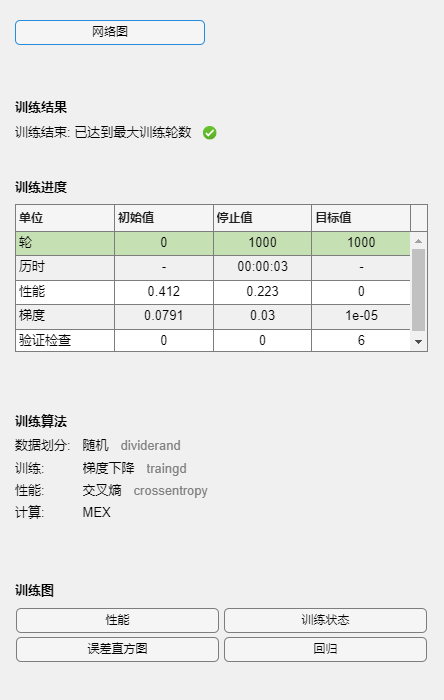


net = train(net, training_x', training_y);

Y = sim(test_x) % return a vector of outputs

'model' 参数必须为字符向量




% % Network Initialization
% numInputs = size(training_x, 2);
% numOutputs = size(species_vec, 1);
% hiddenLayerSize = 10;
% 
% net = patternnet(hiddenLayerSize);
% net = configure(net, training_x', species_vec);
% 
% % Configure the net (with your existing settings)
% % Training
% [net, tr] = train(net, training_x', training_y');
% 
% % Testing
% testOutputs = net(test_x');
% [c, cm] = confusion(test_y', testOutputs);
% 
% fprintf('Percentage Correct Classification   : %f%%\n', 100*(1-c));
% fprintf('Percentage Incorrect Classification : %f%%\n', 100*c);

